## **Proyecto Integrador – SLAM con LiDAR**

En este proyecto se implementa un sistema de construcción de mapas a partir de datos reales del robot MiR100.  

Se emplea el sensor LiDAR (/scan), odometría (/odom) y localización AMCL (/amcl_pose).  

El objetivo es familiarizarse con el pipeline de SLAM: lectura de sensores, predicción, corrección y actualización del mapa.

Cargando rosbag: mir_basics_20251210_114529.bag

Topics disponibles:
    {'/amcl_pose'             }
    {'/base_pose_ground_truth'}
    {'/clock'                 }
    {'/cmd_vel'               }
    {'/imu_data'              }
    {'/joint_states'          }
    {'/map'                   }
    {'/map_metadata'          }
    {'/mir/joint_states'      }
    {'/move_base_simple/goal' }
    {'/odom'                  }
    {'/odometry/filtered'     }
    {'/particlecloud'         }
    {'/scan'                  }
    {'/tf'                    }
    {'/tf_static'             }

Leídos 16636 mensajes de /odom
Leídos 20191 mensajes de /base_pose_ground_truth
Leídos 1397 mensajes de /amcl_pose


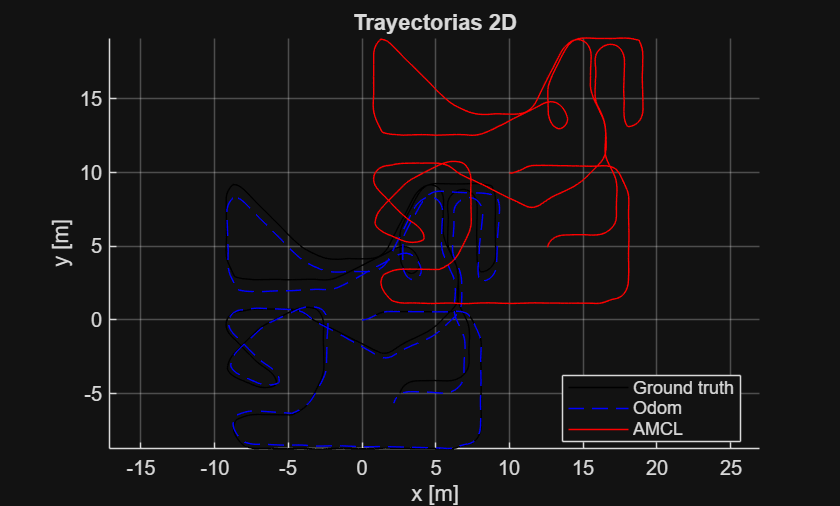

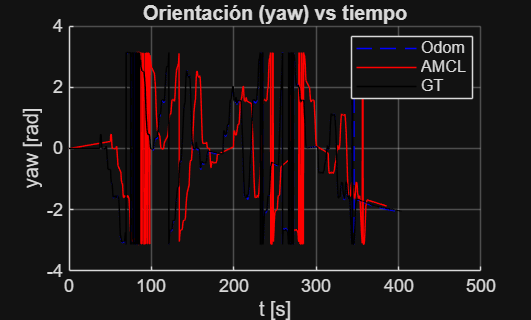


Listo. Revisa las figuras generadas.


%% Proyecto Integrador 2 – SLAM con LiDAR
clearvars; close all; clc;

%% 1) Cargar rosbag
bagFile = 'mir_basics_20251210_114529.bag';
bag = rosbag(bagFile);

% LiDAR
scanMsgs = leerLidarRosbag(bag);

% Odometría, AMCL y Ground Truth (solo gráficas)
analyze_bag(bagFile);

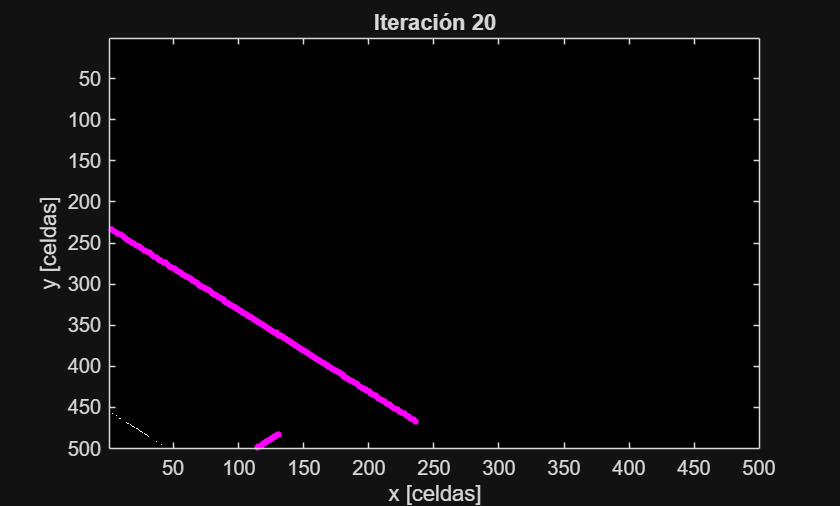


%% 2) Inicializar mapa
mapSize = [500,500]; % celdas
resolution = 0.05;   % 5 cm por celda
p0 = 0.5;
L = log(p0/(1-p0)) * ones(mapSize);
trayectoria = [];

%% 3) Loop principal SLAM
for i = 1:length(scanMsgs)
    % Aquí deberías sincronizar con AMCL si quieres trayectoria real
    % Ejemplo simplificado:
    pose = [0,0,0]; % reemplazar con datos de AMCL

    trayectoria(end+1,:) = [pose(1), pose(2)];
    scanMsg = scanMsgs{i};

    L = actualizarMapaBayesiano(L, pose, scanMsg, resolution);

    if mod(i,20)==0
        dibujarMapaOcupacion(L,trayectoria);
        superponerDeteccionesMapa(L,pose,scanMsg,resolution);
        title(sprintf('Iteración %d',i));
        drawnow;
    end
end


%% 4) Resultados finales
figure;
dibujarMapaOcupacion(L,trayectoria);
title('Mapa final con trayectoria');

disp('SLAM finalizado. Mapa y trayectoria generados.');
